%In this script I will plot the radial velocity distributions of the molecule beam before and after the lens so that I
%can figure out what a the maximum capture velocity of the lens is

load('velocities_39254.mat')

s = size(v_alive{1})

s =      3   616



v = zeros(length(v_alive),s(1),s(2));

for i = 1:length(v_alive)
    v(i,:,:) = v_alive{i};
end

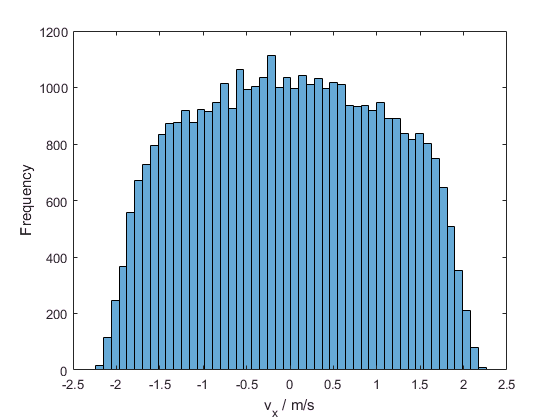


%First plot histograms of velocities before lens
%Plot histogram of x and y- velocities first
figure
histogram(v(:,1,1),'NumBins',50)
xlabel('v_x / m/s')
ylabel('Frequency')

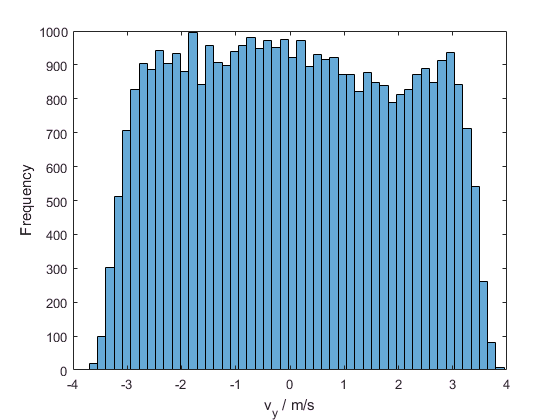


figure
histogram(v(:,2,1),'NumBins',50)
xlabel('v_y / m/s')
ylabel('Frequency')

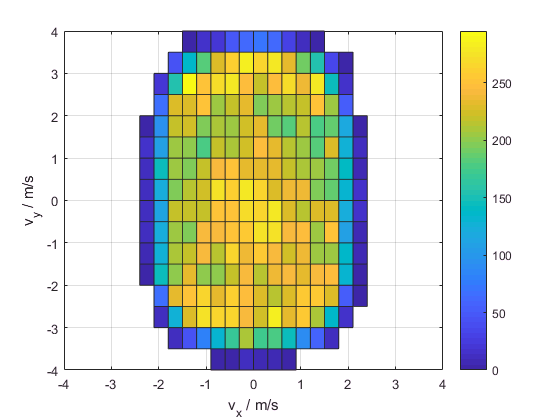


%On the same histogram now:
histogram2(v(:,1,1),v(:,2,1),'DisplayStyle','tile')
xlabel('v_x / m/s')
ylabel('v_y / m/s')
xlim([-4 4])
ylim([-4 4])
colorbar

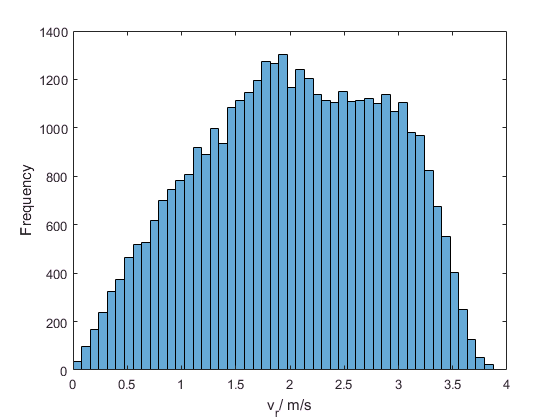


%Next make histogram of radial velocity
v_r = sqrt(v(:,1,:).^2 + v(:,2,:).^2); %calculate radial velocities at each point
figure
histogram(v_r(:,1),'NumBins',50)
xlabel('v_r/ m/s')
ylabel('Frequency')


%What is the max v_r?
max(v_r(:,1))

ans = 3.9104

%What is max v_y?
max(abs(v(:,2,1)))

ans = 3.9099

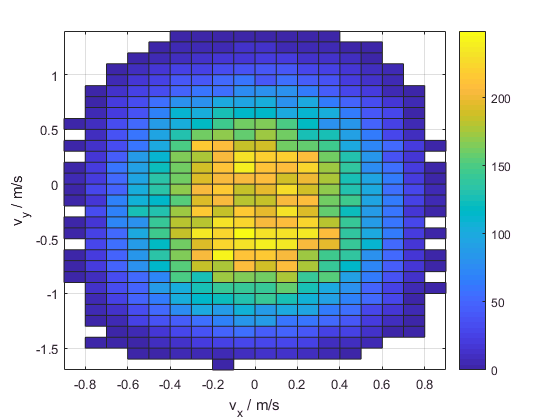

%Velocity distributions after lens
%On the same histogram now:
histogram2(v(:,1,length(v(1,1,:))),v(:,2,length(v(1,1,:))),'DisplayStyle','tile')
xlabel('v_x / m/s')
ylabel('v_y / m/s')
colorbar